3)

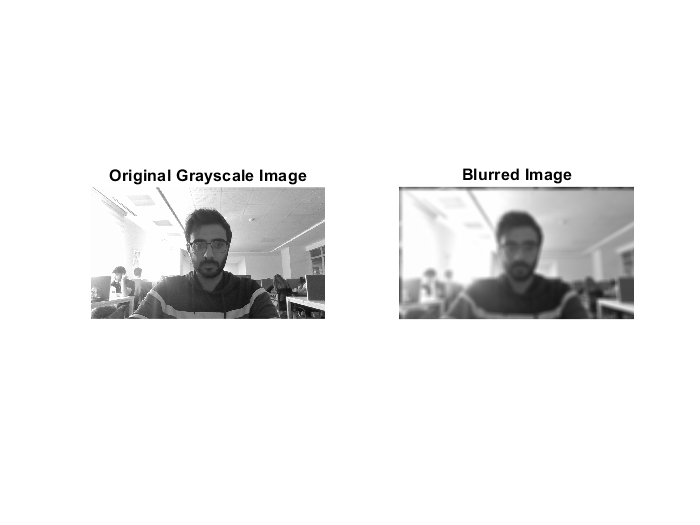

tic;
subplot(1,2,1);
ahmet=imread('C:\Users\ahmet\Desktop\4.sınıf\image\mp4\ahmet.jpg');
ahmet_gray=rgb2gray(ahmet);
ozcan=im2double(ahmet_gray); 
imshow(ozcan);
title('Original Grayscale Image','fontsize', [12]);
 
subplot(1,2,2);
%Take the FFT of your original grayscale image
[x,y]=size(ozcan);
fft_ahmet=fft2(ozcan,x,y);
 
%"n x n" averaging filter in frequency domain 
n=2*round(y/100)+1;     % n=11
m = ones(n);
mask = m/sum(m(:));

%You should use the FFT of the averaging mask
mask_FFT=fft2(mask,x,y);

%Then take the inverse FFT and display the blurred image 
Blur_FFT_Image=fft_ahmet.*mask_FFT;
Blur_Image=ifft2(Blur_FFT_Image);
imshow(Blur_Image);
title('Blurred Image','fontsize', [12]);

 
toc;

Elapsed time is 0.727454 seconds.
